# Plannar R-R DH/mDH setFrameTransform

## Using rigid body tree cell to make a mdh/dh frame rigid body

Learn to use rigid body tree, the Robotics System Toolbox to understand the difference between equation based MDH/DH parameterization, such that the robtoics community using URDF, has it's own single rigid body/single joint in body framework, such that the collision/mass/inertia is embedded on the "linked joint rigid body"

### Purpose

Preassign a circlular path trajectory in work space, and by doing so the angular velocity is mostly constand for the joint space, and wish to make the angular velocity of the joints as smooth and continous as possible, where it will be inverse kinematics calculated.

A starting point on the radius that is pre-assigned, and it does not need to be on the circular trajectory at forst, and thus it need to move onto the circle, tracking and moving towards the path as "pre-assinged time". Thus turning it to be a continous "error tracking" problem.

### Challange

In this case, once the circular path "trajectory error tracking" is established, we will move on to use the Dynamics equation, as well as the assigned gravity/inertia/center of mass to find the calculated torque that is instantanousely "monitored" along the "tracking trajectory". 

It would be physically observed that there is a constant torque during the "tracked" with minimum error moving constant angular velocity for joint movement, or only a small "torque" variation during "acceleration/decellaration", but a more significant "torque" when "acceleration from starting point" as the workspace is initially not on the circular path and exhibits "tacing" error for trying to "catch up" onto the "pre-designed" circular workspace path, and such that the "inverse kinematics" should quickly calculate the needed torque to compensate to such a missmatch..

#### Desing steps:

- setup the rigidRobotTree. Make sure the URDF style robot is setFrameTransform fixed as the R-R planar manipulator, and use both MDH/DH table like framework and can translate to the associated values, so in MDH there are the $x_{1mdh}, x_{2mdh}, x_{3mdh}$ frames, and the DH has the $x_{1dh}, x_{2dh}$ frames. Not to be confused with the joint_1, joint_2 frames of the rigid body tree. As they are the robot rigidBodyTree frames, that helps us to tranform to the $x_{1mdh}, x_{2mdh}, x_{3mdh}$ and $x_{1dh}, x_{2dh}$, when needed to compare to theoratical values.

- once the joint_1, joint_2 along with the body_1, body_2 that is assigned properly, one would use the forward kinematics/inverse kinematics function provided from the robotic system toolbox to design and find the "reference workspace trajectory" and the "reference jointspace trajectory" both for all the "position/velocity/accerlartion" as they are essential for "error tracking". There will be: first a                  open loop operation, then second a "state feedback" close loop operation. Just to feel the "tracking error" being able to become smaller. The former "open loop" should be the basis of collecting all the simulated values. Where first one assign all necessary parameters, such as J_1, J_2, CM_1, CM_2, and all kinematics L_1, L_2 values. With home position (\theta_1, \theta_2) that makes the EOF not on the circular workspace trajectory path. Then this will make the manipulator run with always an "offset" to the designed trajectory. Though inverse kinematics and inverse dynamics will offer a "not-missmatched" perfect trajectory. And since there is no disturbance (no sudden change in inertial/mass/center of mass) in the dynamic sense. Only the "offset from initial condition by home position" will survive all throught the trajectory non-tracking. However the objective in this step is to make sure all values are presented and be able to show "visulization", hopefully with full 3D "missmatch".

- By using the robotics system toolbox, and with "feedback" controller desinged, there should be some pid like movement, where the controller will try to "match" the trajectory. This should show the "dynamic torque" diviation from the previousl "non-feedback/allways missmatch" condition. And to record all the vlues of joint space: angular position/angular velocity/angular accelleration such that they differ from the provious "pre-designed" value. In this case showing "non-adaptive state feedback" on position/velocity (not to feedback force?)

clc;
% clear ??
close all;


## Assigning joint frames first (with mdh in mind) as default

make and show base frame with joint to parent idea {i-1} -> {i}

assign base frame, so to later affix joint frame 1


% using standard frame with original location and standard orientation,
% plot on base figure
eul = [pi/3 pi/2 2]   % euler angles (roll/pitch/yaw or x-/y-/z-) at (0,0,0)

eul =     1.0472    1.5708    2.0000


xyz = [-1.0 +3 pi]   % world location, at (0,0,0)

xyz =    -1.0000    3.0000    3.1416



eul2tform(eul)  % check tranformation and representations

ans =     0.0000    0.8150    0.5794         0
    0.0000    0.5794   -0.8150         0
   -1.0000    0.0000   -0.0000         0
         0         0         0    1.0000


eul2rotm(eul)   % check rotational matrix representations 

ans =     0.0000    0.8150    0.5794
    0.0000    0.5794   -0.8150
   -1.0000    0.0000   -0.0000


eul2quat(eul)   % quaternion representation. remember quaternion is so3

ans =     0.6284    0.3243    0.6284   -0.3243



trvec2tform(xyz)    % tranlation vector to homogenoues tranformation matrix

ans =     1.0000         0         0   -1.0000
         0    1.0000         0    3.0000
         0         0    1.0000    3.1416
         0         0         0    1.0000



tt = se3(eul2rotm(eul), xyz)    % a general se3 object as frame!!!

tt = se3
    0.0000    0.8150    0.5794   -1.0000
    0.0000    0.5794   -0.8150    3.0000
   -1.0000    0.0000   -0.0000    3.1416
         0         0         0    1.0000



fig1 = figure('Name',"Add frame slowly");
ax1 = axes('Parent',fig1);
hold(ax1, 'on');
grid(ax1, 'on');
axis(ax1, 'equal');

plotTransforms(tt, 'Parent', ax1);  % base frame no bodies added!!!
tt.trvec

ans =    -1.0000    3.0000    3.1416


tt.tform

ans =     0.0000    0.8150    0.5794   -1.0000
    0.0000    0.5794   -0.8150    3.0000
   -1.0000    0.0000   -0.0000    3.1416
         0         0         0    1.0000



% rotate tt into base station with new creation

base_frame = se3    % default base station

base_frame = se3
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


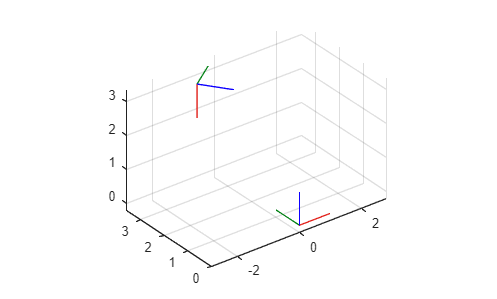


plotTransforms(base_frame, "Parent",ax1)  % showing two frames in same 

### Rigid Body tree creation based on se3(s)

### 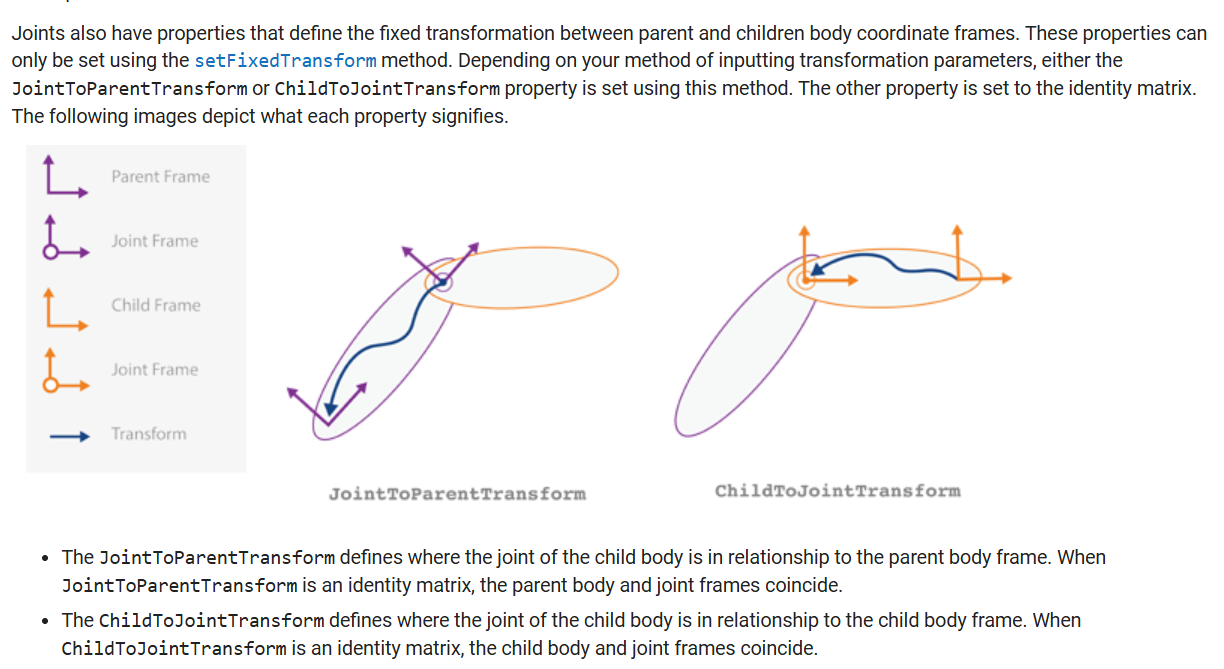

### 1nd frame

%% moving to next frame manually...
eul = [0 0 pi/2];   % turn about z-axis to 45 degrees
xyz = [0 0 1.5];      % move along z-axis to point plus one
quat = eul2quat(eul);   % change euler representation into quaternion representation

tt = tt*trvec2tform(xyz)*quat2tform(quat);  % change (homogeneous multiplication transform) to full se3 matrix

Error using  .*  (line 39)
times, .* requires both operands to be transformations or rotations (of the same type).

Error in  *  (


plotTransforms(xyz, tform2quat(tt), 'Parent', ax1);     % first frame moved up, use above transfomation
                                                    % NOTE!! tt pre-multiplications!! 

### 2rd frame

% 2nd move to next frame
eul = [0 0 0];
xyz = [0 0 1.5];
quat = eul2quat(eul);

tt = tt*trvec2tform(xyz)*quat2tform(quat)   % moved based on most recent moved tt transform, note tt *=

plotTransforms(tform2trvec(tt), tform2quat(tt), 'Parent', ax2);


### 3rd frame

% 3rd move to frame
eul = [0 0 0];
xyz = [0 0 1.5];
quat = eul2quat(eul);

tt = tt*trvec2tform(xyz)*quat2tform(quat)   % moved based on most recent moved tt transform, note tt *=

plotTransforms(tform2trvec(tt), tform2quat(tt), 'Parent', ax2);



## Try with using mdh parameter

making the mdh table

but still needs to be total se3 object 

% make sure rigid body cell names and joints are named
bodies = cell(1,3);
joints = cell(1,3);
jtype = {"revolute","revolute","fixed"};

twolink_robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

[nrow, ncol] = size(bodies);

for i = 1:ncol
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],jtype{i});
end

% with a_1 = 0.5, a_2 = 0.5;
% using theta_1 = pi/3 (param);, theta_2 = pi/4 (param); theta_3 = 0 (fixed);
th1 = pi/7;
th2 = pi/9;
a1 = 0.5;
a2 = 0.5;
th3 = 0;

mdh_param = [0 0 0 th1; a1 0 0 th2; a2 0 0 th3]

mdh_param =          0         0         0    0.4488
    0.5000         0         0    0.3491
    0.5000         0         0         0


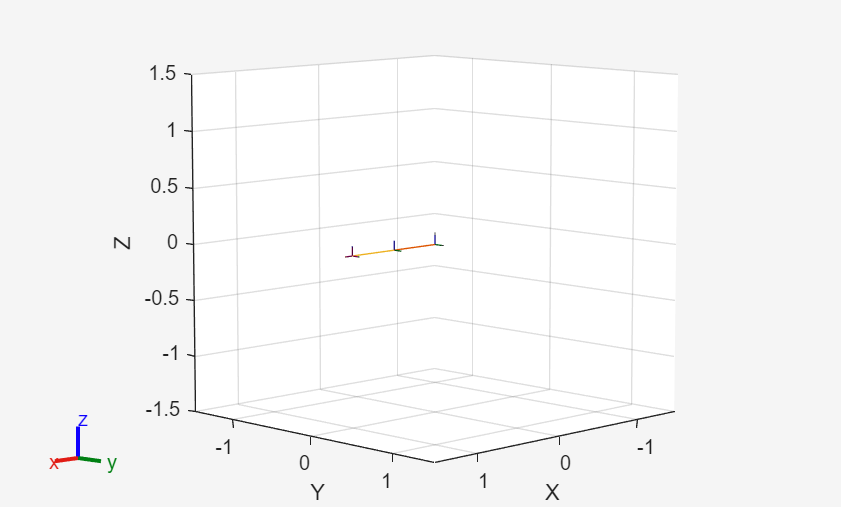


for i = 1:3

    setFixedTransform(joints{i}, mdh_param(i,:),'mdh');
    bodies{i}.Joint = joints{i};

    if i == 1
        addBody(twolink_robot,bodies{i},"base")
    else
        addBody(twolink_robot,bodies{i},bodies{i-1}.Name)
    end
end

fig3 = figure('Name',"2-link Planar Upright Robot");
ax3 = axes('Parent', fig3);
show(twolink_robot, 'Parent', ax3);


showdetails(twolink_robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3        fixed            body2(2)   
--------------------
